# Churn Dataset analysis

Clear workspace

clear all; clc; close all;

## Import data

churn = readtable('churn.csv');
class(churn)

ans = 'table'

churn.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'ID'  'Churned'  'Age'  'Married'  'Cust_years'  'Churned_contacts'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


size(churn)

ans =         8000           6


churn.Properties.VariableNames

ans = 1×6 cell array
    {'ID'}    {'Churned'}    {'Age'}    {'Married'}    {'Cust_years'}    {'Churned_contacts'}


## Data Statistics

s = summary(churn)

s = struct with fields:
                  ID: [1×1 struct]
             Churned: [1×1 struct]
                 Age: [1×1 struct]
             Married: [1×1 struct]
          Cust_years: [1×1 struct]
    Churned_contacts: [1×1 struct]



groupsummary(churn, 'Churned', 'mean')

ans = 2×7 table
    Churned    GroupCount    mean_ID    mean_Age    mean_Married    mean_Cust_years    mean_Churned_contacts
    _______    __________    _______    ________    ____________    _______________    _____________________

       0          6257       3956.2      45.272       0.50008           3.1637                 1.634        
       1          1743       4159.7      27.526       0.50143           3.1635                2.0172        



groupsummary(churn, 'Churned', 'std')

ans = 2×7 table
    Churned    GroupCount    std_ID    std_Age    std_Married    std_Cust_years    std_Churned_contacts
    _______    __________    ______    _______    ___________    ______________    ____________________

       0          6257       2294.5    12.316       0.50004          1.1175               1.2179       
       1          1743       2356.6    7.7988       0.50014          1.1022               1.4043       



groupsummary(churn, 'Churned', 'var')

ans = 2×7 table
    Churned    GroupCount      var_ID      var_Age    var_Married    var_Cust_years    var_Churned_contacts
    _______    __________    __________    _______    ___________    ______________    ____________________

       0          6257       5.2647e+06    151.69       0.25004          1.2488               1.4834       
       1          1743       5.5537e+06    60.821       0.25014          1.2149               1.9721       



gs = groupsummary(churn, 'Churned', 'all')

gs = 2×57 table
    Churned    GroupCount    mean_ID      sum_ID      min_ID    max_ID    range_ID    median_ID    mode_ID      var_ID      std_ID    nummissing_ID    nnz_ID    mean_Age     sum_Age      min_Age    max_Age    range_Age    median_Age    mode_Age    var_Age    std_Age    nummissing_Age    nnz_Age    mean_Married    sum_Married    min_Married    max_Married    range_Married    median_Married    mode_Married    var_Married    std_Ma

gs.var_Age

ans =   151.6889
   60.8212



nchurn=sum(churn.Churned)

nchurn = 1743

ntot = size(churn,1)

ntot = 8000


nchurn/ntot

ans = 0.2179

## Logistic regression

Y = categorical(churn.Churned);
X = table2array(churn(:,3:6));
[B, dev, stats] = mnrfit(X,Y,model='nominal')

B =    -3.4152
    0.1566
   -0.0664
   -0.0179
   -0.3823


dev = 5.3579e+03

stats = struct with fields:
         beta: [5×1 double]
          dfe: 7995
         sfit: 1.0106
            s: 1
      estdisp: 0
         covb: [5×5 double]
    coeffcorr: [5×5 double]
           se: [5×1 double]
            t: [5×1 double]
            p: [5×1 double]
        resid: [8000×2 double]
       residp: [8000×2 double]
       residd: [8000×1 double]



[stats.beta stats.p]

ans =    -3.4152    0.0000
    0.1566    0.0000
   -0.0664    0.3307
   -0.0179    0.5582
   -0.3823    0.0000


### Complete model

modelspec = ['Churned ~ Age + Married + Cust_years + Churned_contacts'];
mdl = fitglm(churn, modelspec, Distribution='binomial')

mdl = Generalized linear regression model:
    logit(Churned) ~ 1 + Age + Married + Cust_years + Churned_contacts
    Distribution = Binomial

Estimated Coefficients:
                        Estimate       SE         tStat       pValue   
                        ________    _________    _______    ___________

    (Intercept)           3.4152      0.16373     20.858     1.2863e-96
    Age                 -0.15664    0.0040878     -38.32    2.9051e-321
    Married             0.066432     0.068302    0.97262        0.33074
    Cust_years          0.017857     0.030497    0.58552         0.5582
    Churned_contacts     0.38232     0.027313     13.998     1.6104e-44


8000 observations, 7995 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 3.03e+

### Remove Cust_years as it is the least significative

modelspec = ['Churned ~ Age + Married + Churned_contacts'];
mdl = fitglm(churn, modelspec, Distribution='binomial')

mdl = Generalized linear regression model:
    logit(Churned) ~ 1 + Age + Married + Churned_contacts
    Distribution = Binomial

Estimated Coefficients:
                        Estimate       SE         tStat       pValue   
                        ________    _________    _______    ___________

    (Intercept)           3.4721      0.13211     26.282    3.0816e-152
    Age                 -0.15663    0.0040877    -38.318    3.0533e-321
    Married              0.06643     0.068299    0.97262        0.33074
    Churned_contacts     0.38191     0.027302     13.988     1.8346e-44


8000 observations, 7996 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 3.03e+03, p-value = 0

### Remove also Married

modelspec = ['Churned ~ Age + Churned_contacts'];
mdl = fitglm(churn, modelspec, Distribution='binomial')

mdl = Generalized linear regression model:
    logit(Churned) ~ 1 + Age + Churned_contacts
    Distribution = Binomial

Estimated Coefficients:
                        Estimate       SE         tStat       pValue   
                        ________    _________    _______    ___________

    (Intercept)           3.5027      0.12843     27.273    8.8099e-164
    Age                 -0.15655    0.0040851    -38.322    2.6087e-321
    Churned_contacts     0.38186     0.027297     13.989     1.8183e-44


8000 observations, 7997 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 3.03e+03, p-value = 0


% p-values indicating significancy of model parameters
mdl.Deviance

ans = 5.3592e+03

mdl.Rsquared

ans = struct with fields:
          Ordinary: 0.3710
          Adjusted: 0.3709
               LLR: 0.3610
          Deviance: 0.3610
    AdjGeneralized: 0.4852


mdl.DFE

ans = 7997

mdl.LogLikelihood

ans = -2.6796e+03

r = mdl.Residuals.Raw;

Model predictions

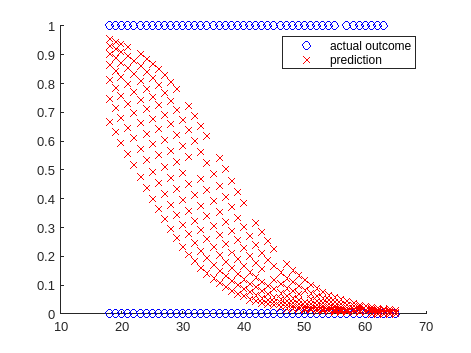

ypred = predict(mdl,churn);

figure(1)
clf
hold on
plot(churn.Age, churn.Churned, 'bo', DisplayName='actual outcome')
plot(churn.Age, ypred, 'rx', DisplayName='prediction')
legend
hold off

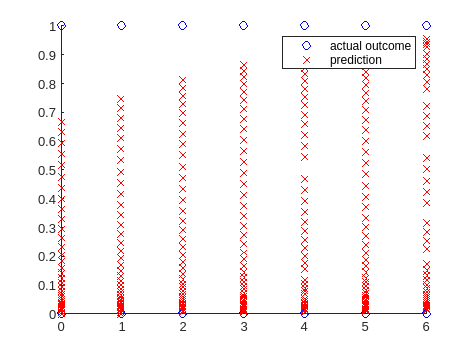


figure(2)
clf
hold on
plot(churn.Churned_contacts, churn.Churned, 'bo', DisplayName='actual outcome')
plot(churn.Churned_contacts, ypred, 'rx', DisplayName='prediction')
legend
hold off

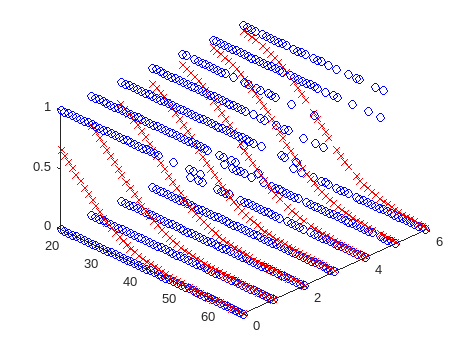


figure(3)
clf
hold on
plot3(churn.Age, churn.Churned_contacts, churn.Churned, 'bo', DisplayName='actual outcome')
plot3(churn.Age, churn.Churned_contacts, ypred, 'rx', DisplayName='prediction')
view([45 45])
hold off


scores = mdl.Fitted.Probability;

## ROC curve

[X, Y, T, AUC] = perfcurve(churn.Churned, scores, '1');
AUC

AUC = 0.8877

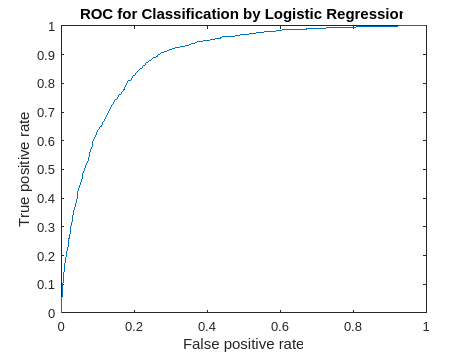


figure(4)
plot(X,Y)
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC for Classification by Logistic Regression')

### TPR & FPR

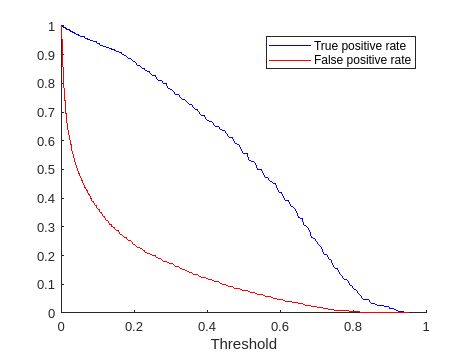

fpr = X;
tpr = Y;
th = T;

figure(5)
clf
hold on 
plot(th,tpr,'b-',DisplayName='True positive rate')
plot(th,fpr,'r-',DisplayName='False positive rate')
xlabel('Threshold')
legend
hold off

## Histogram

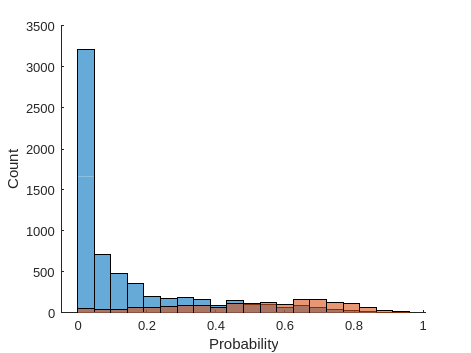

sc1 = scores(churn.Churned==1);
sc0 = scores(churn.Churned==0);

figure(6)
clf
hold on
histogram(sc0,20,DisplayName='Remained')
histogram(sc1,20,DisplayName='Churned')
xlabel('Probability')
ylabel('Count')
hold off